# How Big Are the Pixels?

This example shows how to determine the approximate physical extent of image pixels as currently displayed, and then it shows how to adjust the zoom level so that the pixels have a specified extent.

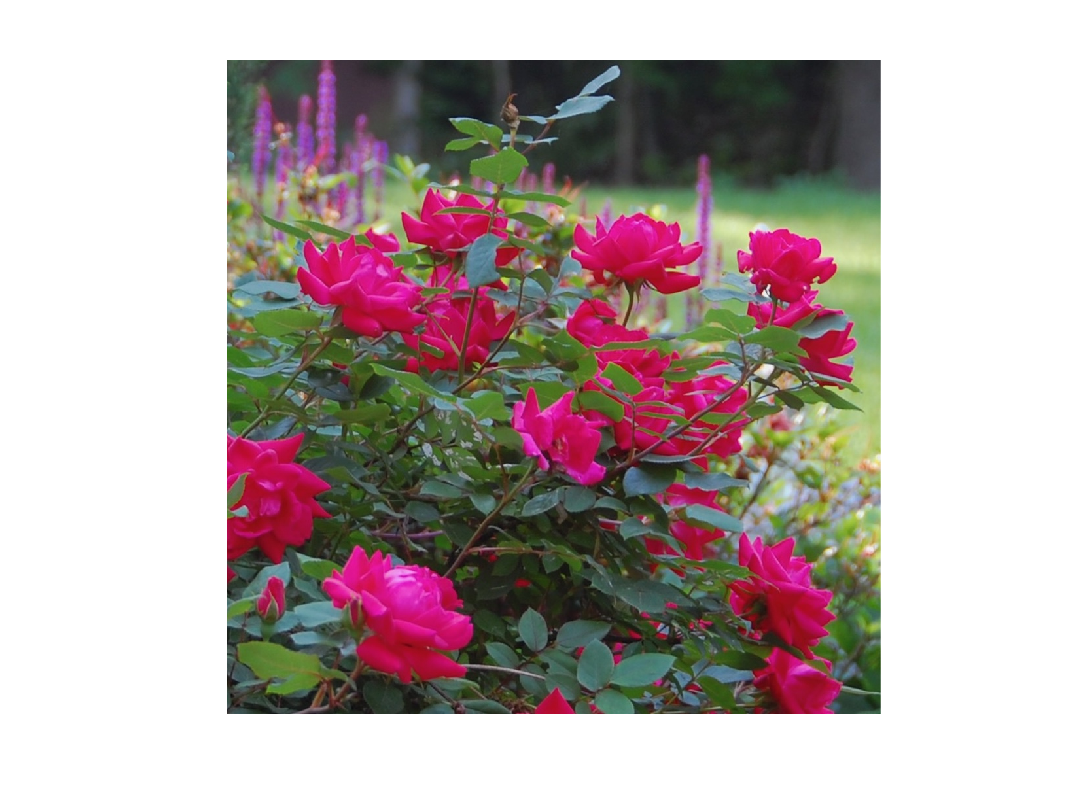

A = imread("roses-se.jpg");
imshow(A)

How big are the image pixels?

ext = getImagePixelExtentInches

ext =     0.0036    0.0036


Now set the zoom level so that the pixel width and height are approximately 0.25 inches.

level = getImageZoomLevel

level =    34.2667   34.2667


new_level = level .* (0.25 ./ ext)

new_level = 1.0e+03 *

    2.4000    2.4000


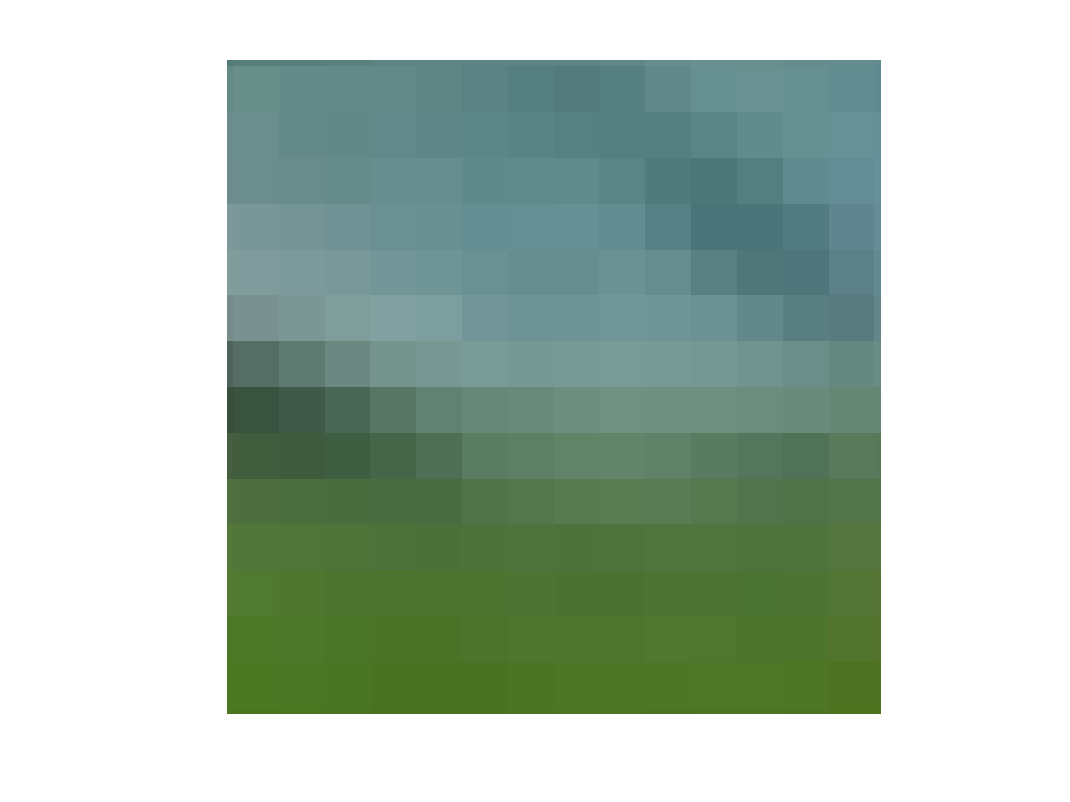

setImageZoomLevel(new_level)

% Shift the image down a bit so that we are not looking an
% almost constant region.
setAxesCenterXY(getAxesCenterXY - [10 0])

**Note**: The output of `getImagePixelExtentInches` is only a rough approximation of the physical extent of pixels in true inches.